# SDI New Noise Running Randy's MM code multiple times to generate uncorrelated noise

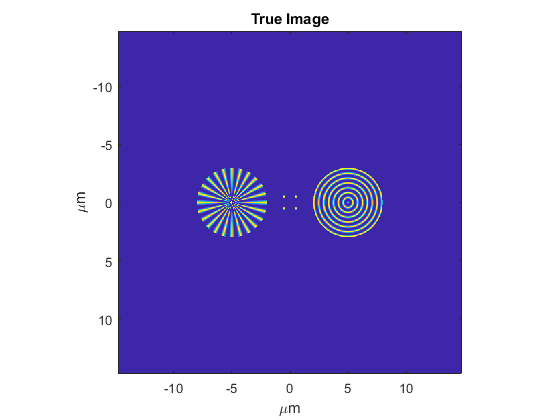

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SDI\MPSFIFforSDI\NewSDIData")
clear variables
%load grids

x=load('xspatvec.mat');
x=x.Expression1;
fx=load('xspatfreq.mat');
fx=fx.Expression1;
y=load('yspatvec.mat');
y=y.Expression1;
fy=load('yspatfreq.mat');
fy=fy.Expression1;
trueimage=load("trueimage.mat");
trueimage=trueimage.Expression1;
figure; imagesc(x,y,trueimage)
xlabel('\mum')
ylabel('\mum')
axis square
title('True Image')

Load Blurry Images

% Noisy ones
for jj=1:4
    s=load(strcat('imgN2',num2str(jj),'.mat'));
    imgN2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('imgN3',num2str(jj),'.mat'));
    imgN3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
for jj=1:4
    
    imgN2N(:,:,jj)=Norm(imgN2(:,:,jj));
end
for jj=1:6
    
    imgN3N(:,:,jj)=Norm(imgN3(:,:,jj));
end 

for ii=1:4
    if ii==1
        imgN2new(:,:,:,ii)=imgN2;
    else
        for jj=1:4
            s=load(strcat('imgN2',num2str(jj),num2str(ii-1),'.mat'));
            imgN2new(:,:,jj,ii)=s.Expression1;
        end
    end
end

for ii=1:6
    if ii==1
        imgN3new(:,:,:,ii)=imgN3;
    else
        for jj=1:6
            s=load(strcat('imgN3',num2str(jj),num2str(ii-1),'.mat'));
            imgN3new(:,:,jj,ii)=s.Expression1;
        end
    end
end

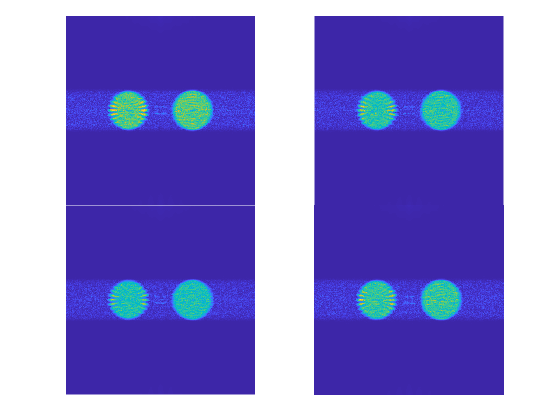


figure;
t=tiledlayout(2,2);
nexttile
imagesc(imgN2new(:,:,1,1))
axis square
axis off
nexttile
imagesc(imgN2new(:,:,1,2))
axis square
axis off
nexttile
imagesc(imgN2new(:,:,1,3))
axis square
axis off
nexttile
imagesc(imgN2new(:,:,1,4))
axis square
axis off
t.TileSpacing = 'none';
t.Padding = 'compact';

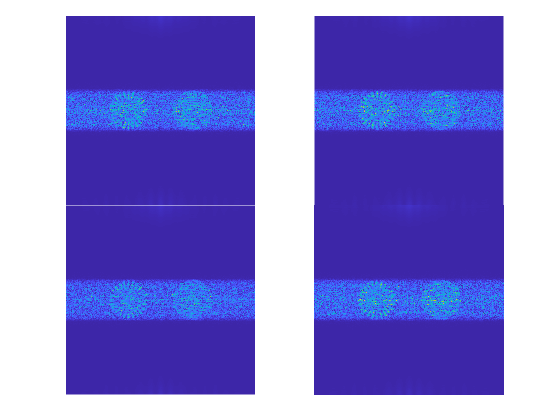


figure;
t=tiledlayout(2,2);
nexttile
imagesc(imgN2new(:,:,3,1))
axis square
axis off
nexttile
imagesc(imgN2new(:,:,3,2))
axis square
axis off
nexttile
imagesc(imgN2new(:,:,3,3))
axis square
axis off
nexttile
imagesc(imgN2new(:,:,3,4))
axis square
axis off
t.TileSpacing = 'none';
t.Padding = 'compact';

Great Noise now seems uncorrelated

Load Noise Free Versions

% Noise Free ones
for jj=1:4
    s=load(strcat('imgNF2',num2str(jj),'.mat'));
    imgNF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('imgNF3',num2str(jj),'.mat'));
    imgNF3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
for jj=1:4
    
    imgNF2N(:,:,jj)=Norm(imgNF2(:,:,jj));
end
for jj=1:6
    
    imgNF3N(:,:,jj)=Norm(imgNF3(:,:,jj));
end   

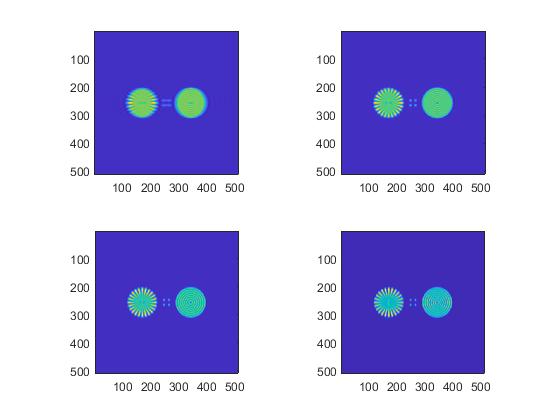

figure;
subplot(2,2,1)
imagesc(imgNF2(:,:,1))
axis square
subplot(2,2,2)
imagesc(imgNF2(:,:,2))
axis square
subplot(2,2,3)
imagesc(imgNF2(:,:,3))
axis square
subplot(2,2,4)
imagesc(imgNF2(:,:,4))
axis square

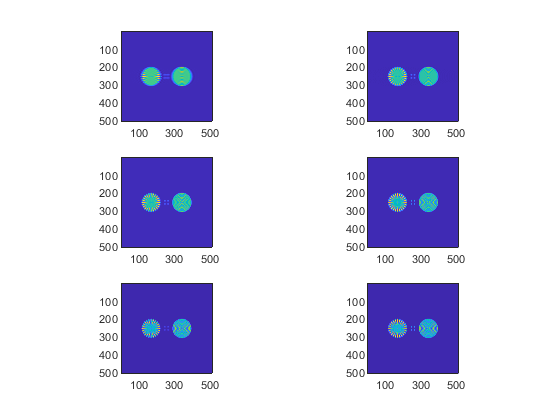


figure;
subplot(3,2,1)
imagesc(imgNF3(:,:,1))
axis square
subplot(3,2,2)
imagesc(imgNF3(:,:,2))
axis square
subplot(3,2,3)
imagesc(imgNF3(:,:,3))
axis square
subplot(3,2,4)
imagesc(imgNF3(:,:,4))
axis square
subplot(3,2,5)
imagesc(imgNF3(:,:,5))
axis square
subplot(3,2,6)
imagesc(imgNF3(:,:,6))
axis square

Load OTFs

for jj=1:4
    s=load(strcat('OTF2',num2str(jj),'.mat'));
    OTF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('OTF3',num2str(jj),'.mat'));
    OTF3(:,:,jj)=s.Expression1;
end    

for jj=1:4
    s=load(strcat('OTF2',num2str(jj),'c','.mat'));
    OTF2c(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('OTF3',num2str(jj),'c','.mat'));
    OTF3c(:,:,jj)=s.Expression1;
end   

Turn into PSFs (Above OTFs are not complex??)

for ii=1:4
    PSF2(:,:,ii)=abs(ifftshift(ifft2(OTF2(:,:,ii))));
end
for ii=1:6
    PSF3(:,:,ii)=abs(ifftshift(ifft2(OTF3(:,:,ii))));
end
% Normalized Versions
for ii=1:4
    PSF2N(:,:,ii)=Norm(PSF2(:,:,ii));
end
for ii=1:6
    PSF3N(:,:,ii)=Norm(PSF3(:,:,ii));
end

% Using Complex OTFs
for ii=1:4
    PSF2c(:,:,ii)=abs(ifftshift(ifft2(OTF2c(:,:,ii))));
end
for ii=1:6
    PSF3c(:,:,ii)=abs(ifftshift(ifft2(OTF3c(:,:,ii))));
end

% Normalized Versions
for ii=1:4
    PSF2cN(:,:,ii)=Norm(PSF2c(:,:,ii));
end
for ii=1:6
    PSF3cN(:,:,ii)=Norm(PSF3c(:,:,ii));
end

for ii=1:4
    imgN2new1(:,:,ii)=imgN2new(:,:,ii,ii);
end

for ii=1:6
    imgN3new1(:,:,ii)=imgN3new(:,:,ii,ii);
end

% Normalized
for ii=1:4
    imgN2new1N(:,:,ii)=Norm(imgN2new1(:,:,ii));
end

for ii=1:6
    imgN3new1N(:,:,ii)=Norm(imgN3new1(:,:,ii));
end

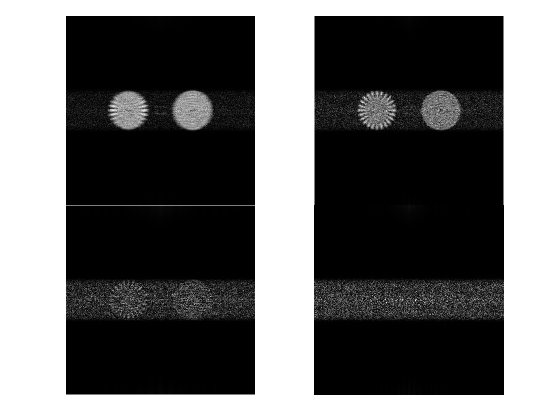

figure;
t=tiledlayout(2,2);
nexttile
imagesc(imgN2new1(:,:,1))
axis square
axis off
colormap gray
nexttile
imagesc(imgN2new1(:,:,2))
axis square
axis off
colormap gray
nexttile
imagesc(imgN2new1(:,:,3))
axis square
axis off
colormap gray
nexttile
imagesc(imgN2new1(:,:,4))
axis square
axis off
colormap gray
t.TileSpacing = 'none';
t.Padding = 'compact';

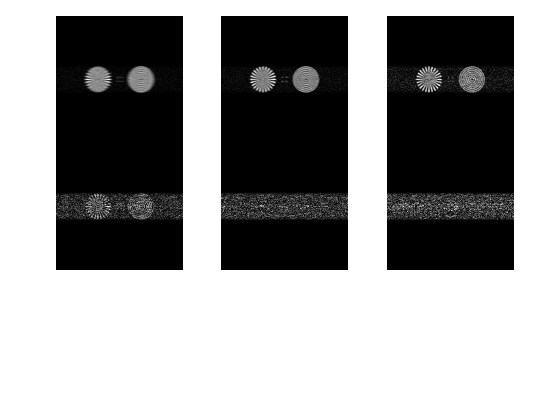


figure;
t=tiledlayout(3,3);
nexttile
imagesc(imgN3new1(:,:,1))
axis square
axis off
colormap gray
nexttile
imagesc(imgN3new1(:,:,2))
axis square
axis off
colormap gray
nexttile
imagesc(imgN3new1(:,:,3))
axis square
axis off
colormap gray
nexttile
imagesc(imgN3new1(:,:,4))
axis square
axis off
colormap gray
nexttile
imagesc(imgN3new1(:,:,5))
axis square
axis off
colormap gray
nexttile
imagesc(imgN3new1(:,:,6))
axis square
axis off
colormap gray
t.TileSpacing = 'none';
t.Padding = 'compact';

s=size(PSF3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN3new1N,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 142.034053 seconds.


clear recMPIMN3 errorrecrecMPIMN3
recMPIMN3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0045

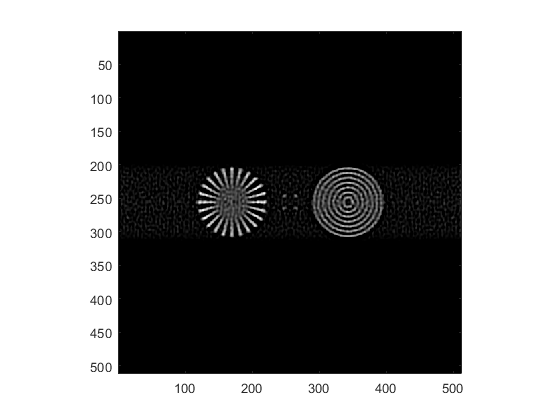

for ii=1:size(recMPIMN3,3)
    errorrecrecMPIMN3(ii)=immse(Norm(trueimage),Norm(recMPIMN3(:,:,ii)));
end

[eval locm]=min(errorrecrecMPIMN3);
figure; imagesc(recMPIMN3(:,:,locm))
axis square
colormap gray

save('imgN3ReconUnCorrNoise.mat','recMPIMN3','-v7.3','-nocompression');

s=size(PSF3N(:,:,1:5));
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N(:,:,1:5),[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN3new1N(:,:,1:5),[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 123.354252 seconds.


clear recMPIMN32 errorrecrecMPIMN32
recMPIMN32=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0053

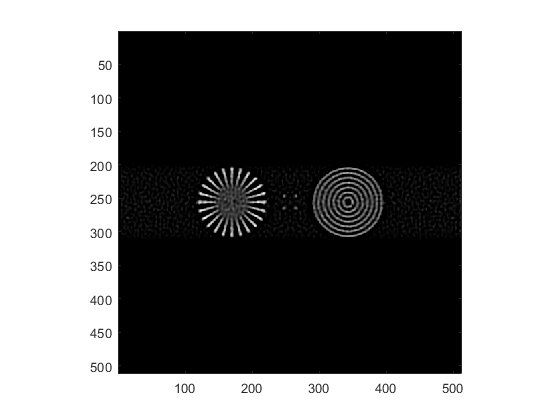

for ii=1:size(recMPIMN32,3)
    errorrecrecMPIMN32(ii)=immse(Norm(trueimage),Norm(recMPIMN32(:,:,ii)));
end

[eval3 locm3]=min(errorrecrecMPIMN32);
figure; imagesc(recMPIMN32(:,:,locm3))
axis square
colormap gray

s=size(PSF3N(:,:,1:4));
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N(:,:,1:4),[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN3new1N(:,:,1:4),[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 89.830741 seconds.


clear recMPIMN33 errorrecrecMPIMN33
recMPIMN33=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0129

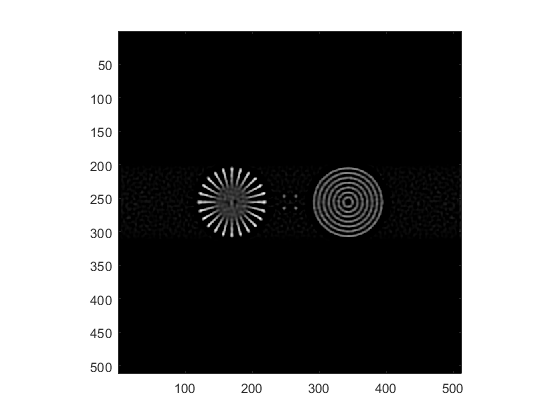

for ii=1:size(recMPIMN33,3)
    errorrecrecMPIMN33(ii)=immse(Norm(trueimage),Norm(recMPIMN33(:,:,ii)));
end

[eval4 locm4]=min(errorrecrecMPIMN33);
figure; imagesc(recMPIMN33(:,:,locm4))
axis square
colormap gray

s=size(PSF2N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN2new1N,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 90.118360 seconds.


clear recMPIMN2 errorrecrecMPIMN2
recMPIMN2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0037

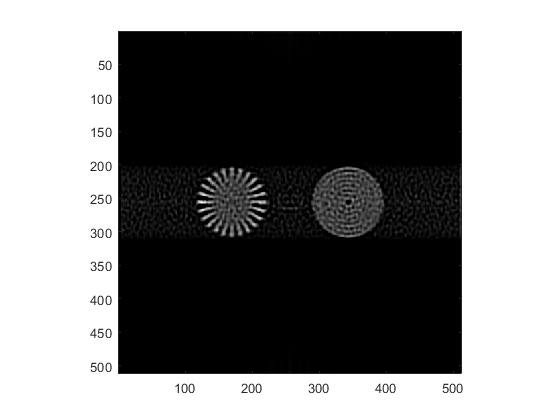

for ii=1:size(recMPIMN2,3)
    errorrecrecMPIMN2(ii)=immse(Norm(trueimage),Norm(recMPIMN2(:,:,ii)));
end

[eval2 locm2]=min(errorrecrecMPIMN2);
figure; imagesc(recMPIMN2(:,:,locm2))
axis square
colormap gray

save('imgN2ReconUnCorrNoise.mat','recMPIMN2','-v7.3','-nocompression');

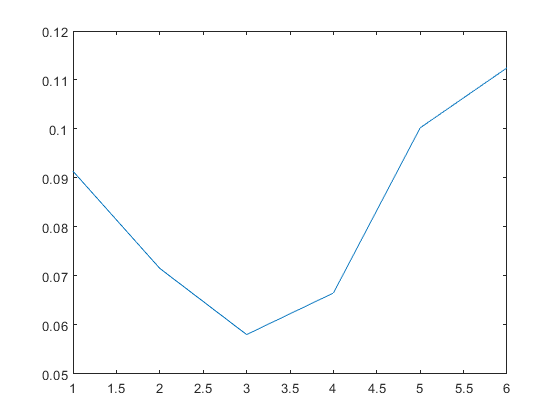

% Error in Each Harmonic image (Adding Noise to Randy's)
for ii=1:size(imgN3new1N,3)
    errorharmsRGN3(ii)=immse(Norm(imgN3new1N(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imgN2new1N,3)
    errorharmsRGN2(ii)=immse(Norm(imgN2new1N(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
figure; plot(errorharmsRGN3)

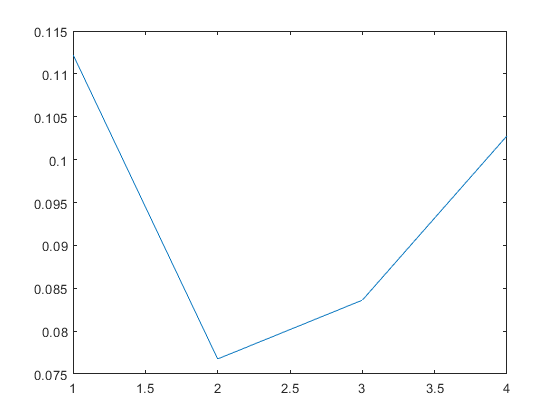

figure; plot(errorharmsRGN2)

% Corresponding error in reconstructions
eval

eval = 0.0042

eval2

eval2 = 0.0071


%lines 637-693

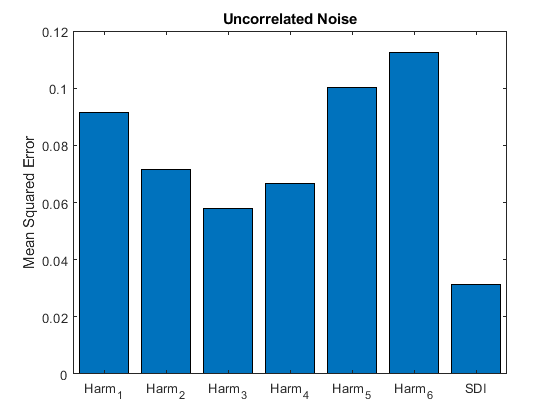

X = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','Harm_5','Harm_6','SDI'});

Y = [errorharmsRGN3(1) errorharmsRGN3(2) errorharmsRGN3(3) errorharmsRGN3(4) errorharmsRGN3(5) errorharmsRGN3(6) immse(Norm(recMPIMN3(200:311,112:400,locm)),Norm(trueimage(200:311,112:400)))];
figure;
bar(X,Y)
ylabel('Mean Squared Error')
title('Uncorrelated Noise')

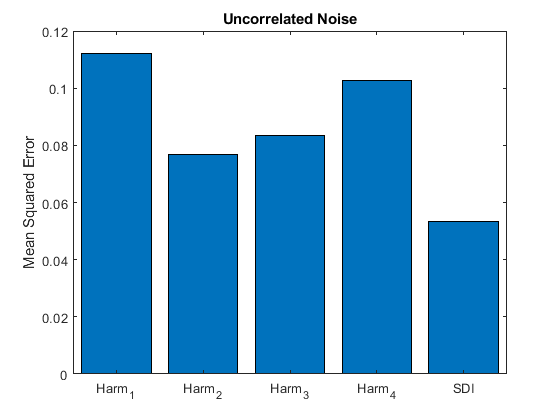

X2 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','SDI'});

Y2 = [errorharmsRGN2(1) errorharmsRGN2(2) errorharmsRGN2(3) errorharmsRGN2(4) immse(Norm(recMPIMN2(200:311,112:400,locm2)),Norm(trueimage(200:311,112:400)))];
figure;
bar(X2,Y2)
ylabel('Mean Squared Error')
title('Uncorrelated Noise')

X3 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','Harm_5','Harm_6','SDI'});

% Y3 = [errorharmsGN3(1) errorharmsGN3(2) errorharmsGN3(3) errorharmsGN3(4) errorharmsGN3(5) errorharmsGN3(6) immse(Norm(recMPIMGN3v2(200:311,112:400,locm3v2)),Norm(trueimage(200:311,112:400)))];
% figure;
% bar(X3,Y3)
% ylabel('Mean Squared Error')
% title('Gnoise')
% 
% X4 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','SDI'});
% 
% Y4 = [errorharmsGN2(1) errorharmsGN2(2) errorharmsGN2(3) errorharmsGN2(4) immse(Norm(recMPIMGN2v2(200:311,112:400,locm2v2)),Norm(trueimage(200:311,112:400)))];
% figure;
% bar(X4,Y4)
% ylabel('Mean Squared Error')
% title('Gnoise')

RGN3=recMPIMN3(:,:,locm);
RGN2=recMPIMN2(:,:,locm2);

save('ReconstructedNoisyImagesUnCorrNoise.mat','RGN3','RGN2');

Ntheta=20;
trueimFave=GabeRadialAvg(abs(fftshift(fft2(trueimage))),Ntheta);
FaveRGN3=GabeRadialAvg(abs(fftshift(fft2(RGN3))),Ntheta);
FaveRGN2=GabeRadialAvg(abs(fftshift(fft2(RGN2))),Ntheta);
% FaveGN3=GabeRadialAvg(abs(fftshift(fft2(GN3))),Ntheta);
% FaveGN2=GabeRadialAvg(abs(fftshift(fft2(GN2))),Ntheta);
% FaveNF3=GabeRadialAvg(abs(fftshift(fft2(NF3))),Ntheta);
% FaveNF2=GabeRadialAvg(abs(fftshift(fft2(NF2))),Ntheta);

FaveGN3H1=GabeRadialAvg(abs(fftshift(fft2(imgN3new1N(:,:,1)))),Ntheta);
FaveGN3H2=GabeRadialAvg(abs(fftshift(fft2(imgN3new1N(:,:,2)))),Ntheta);
FaveGN3H3=GabeRadialAvg(abs(fftshift(fft2(imgN3new1N(:,:,3)))),Ntheta);
FaveGN3H4=GabeRadialAvg(abs(fftshift(fft2(imgN3new1N(:,:,4)))),Ntheta);
FaveGN3H5=GabeRadialAvg(abs(fftshift(fft2(imgN3new1N(:,:,5)))),Ntheta);
FaveGN3H6=GabeRadialAvg(abs(fftshift(fft2(imgN3new1N(:,:,6)))),Ntheta);


FaveGN2H1=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,1)))),Ntheta);
FaveGN2H2=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,2)))),Ntheta);
FaveGN2H3=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,3)))),Ntheta);
FaveGN2H4=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,4)))),Ntheta);
% FaveRGNH1=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,1)))),Ntheta);
% FaveRGNH2=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,2)))),Ntheta);
% FaveRGNH3=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,3)))),Ntheta);
% FaveRGNH4=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,4)))),Ntheta);
% FaveRGNH5=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,5)))),Ntheta);
% FaveRGNH6=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,6)))),Ntheta);
% 
% FaveNF3H1=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,1)))),Ntheta);
% FaveNF3H2=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,2)))),Ntheta);
% FaveNF3H3=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,3)))),Ntheta);
% FaveNF3H4=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,4)))),Ntheta);
% FaveNF3H5=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,5)))),Ntheta);
% FaveNF3H6=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,6)))),Ntheta);
% 
% FaveN3H1=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,1)))),Ntheta);
% FaveN3H2=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,2)))),Ntheta);
% FaveN3H3=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,3)))),Ntheta);
% FaveN3H4=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,4)))),Ntheta);
% FaveN3H5=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,5)))),Ntheta);
% FaveN3H6=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,6)))),Ntheta);

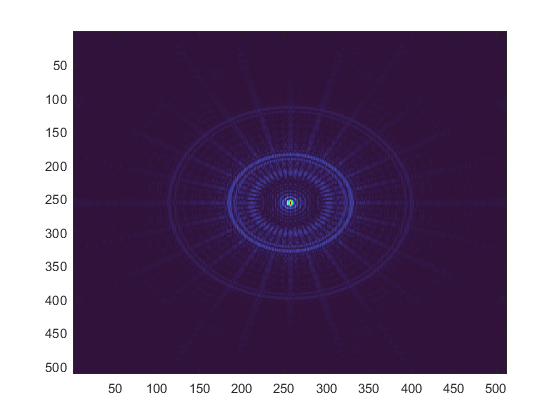

figure; imagesc((abs(fftshift(fft2(trueimage)))))
colormap Turbo

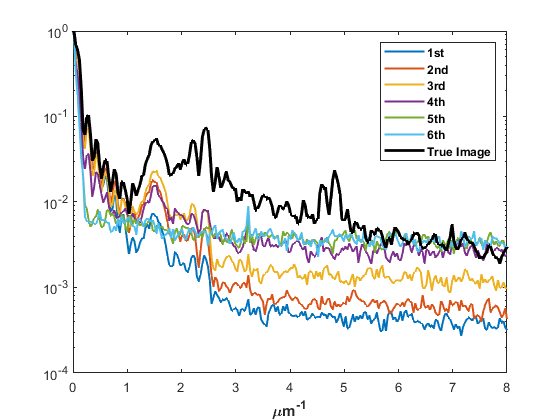

figure; semilogy(fx,(Norm(FaveGN3H1)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('\mum^{-1}','FontWeight','Bold')
legend({'1st','2nd','3rd','4th','5th','6th','True Image'},'FontWeight','Bold')

% semilogy((Norm(FaveN3H5(end/2:end))))
% semilogy((Norm(FaveN3H6(end/2:end))))

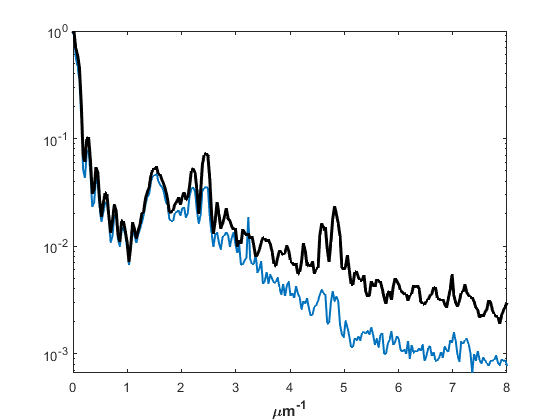

figure; semilogy(fx,(Norm(FaveRGN3)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


% semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('\mum^{-1}','FontWeight','Bold')

%legend({'1st','2nd','3rd','4th','5th','6th','True Image'},'FontWeight','Bold')
% semilogy((Norm(FaveN3H5(end/2:end))))
% semilogy((Norm(FaveN3H6(end/2:end))))

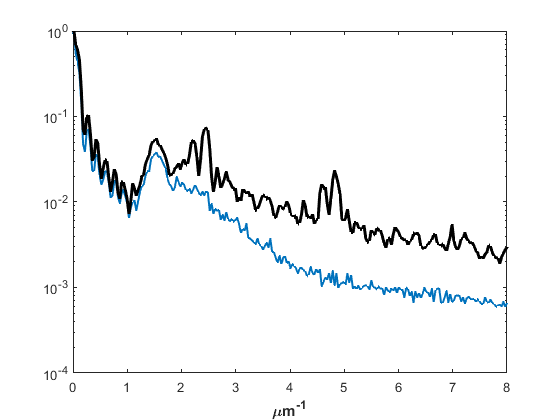

figure; semilogy(fx,(Norm(FaveRGN2)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


% semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('\mum^{-1}','FontWeight','Bold')

%legend({'1st','2nd','3rd','4th','5th','6th','True Image'},'FontWeight','Bold')
% semilogy((Norm(FaveN3H5(end/2:end))))
% semilogy((Norm(FaveN3H6(end/2:end))))

TrueimF=abs(fftshift(fft2(trueimage)));
FRGN3=abs(fftshift(fft2(RGN3)));
FRGN2=abs(fftshift(fft2(RGN2)));

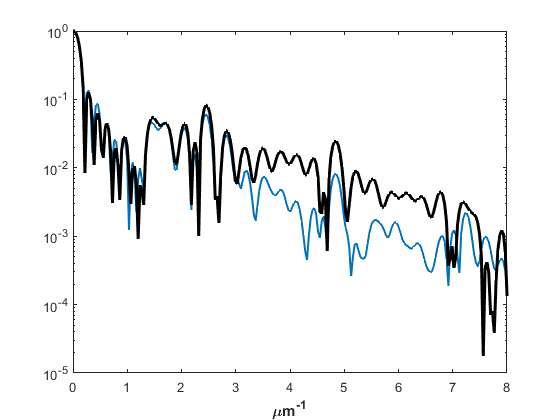

figure; semilogy(fx,(Norm(FRGN3(:,end/2+1))),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


% semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(TrueimF(:,end/2+1))),'k','LineWidth',2)
xlim([0 8])
xlabel('\mum^{-1}','FontWeight','Bold')

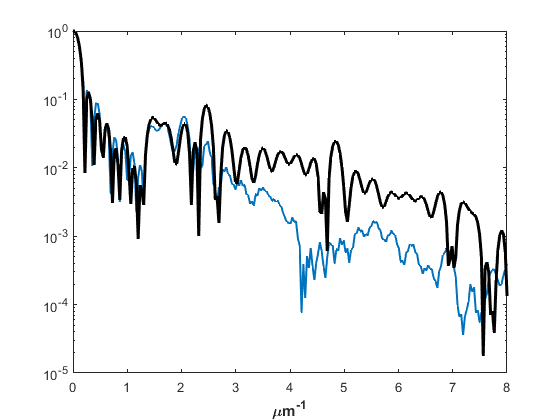


figure; semilogy(fx,(Norm(FRGN2(:,end/2+1))),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


% semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(TrueimF(:,end/2+1))),'k','LineWidth',2)
xlim([0 8])
xlabel('\mum^{-1}','FontWeight','Bold')

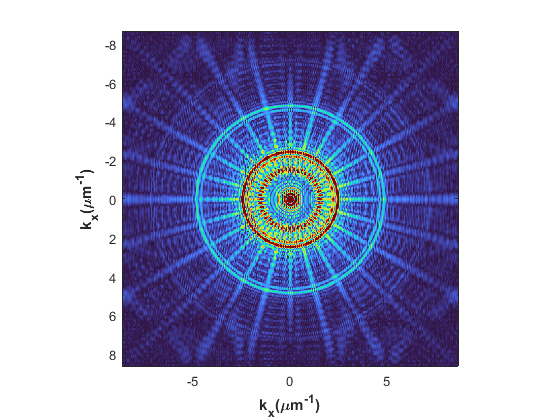


figure; imagesc(fx,fx,Norm((TrueimF)))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

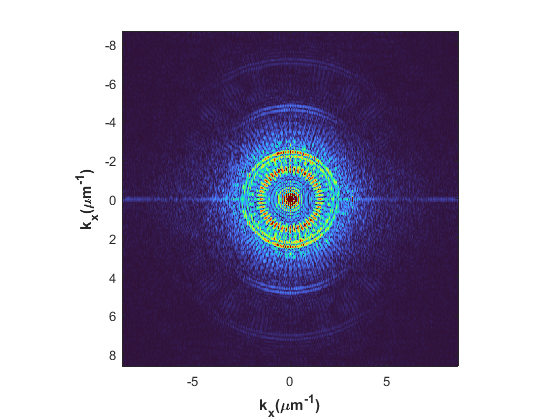

figure; imagesc(fx,fx,Norm((FRGN3)))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

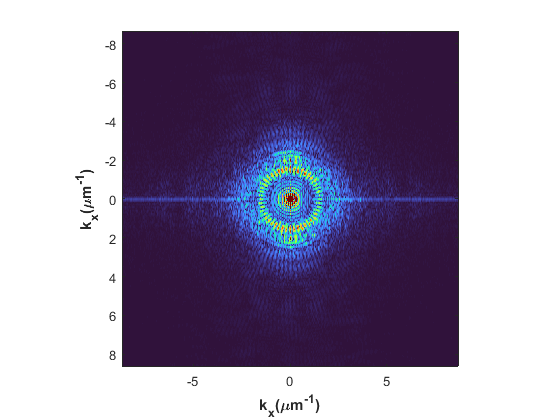

figure; imagesc(fx,fx,Norm(FRGN2))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

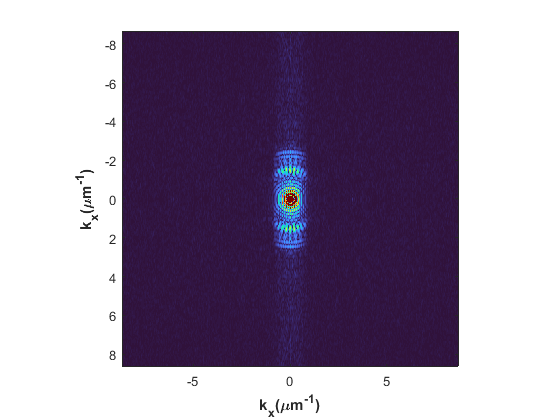

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3new1(:,:,1))))))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

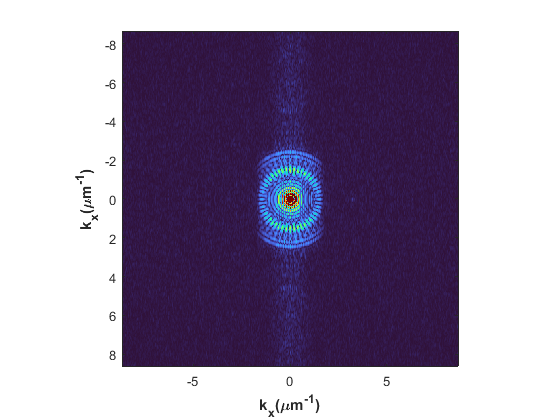

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3new1(:,:,2))))))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

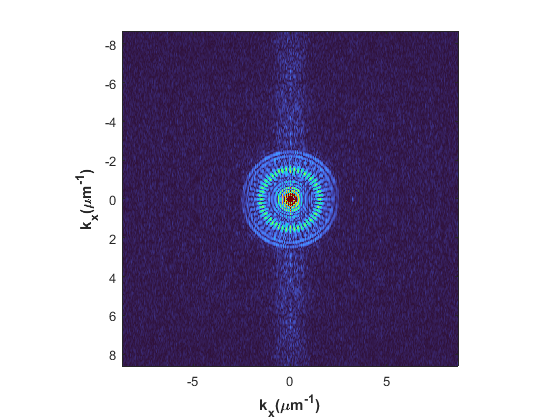

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3new1(:,:,3))))))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

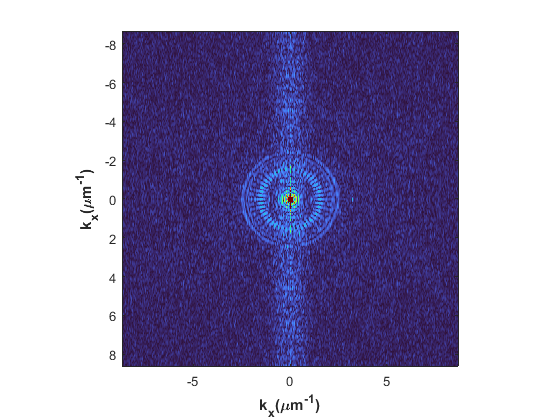

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3new1(:,:,4))))))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

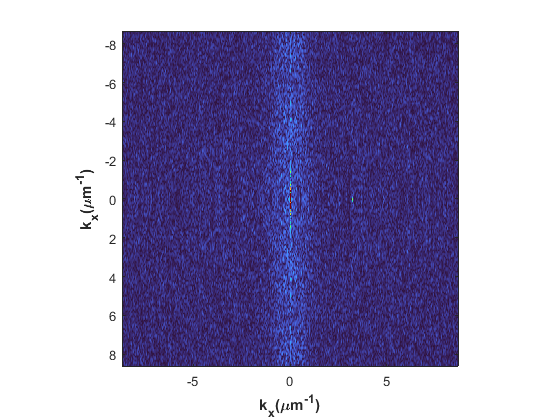

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3new1(:,:,5))))))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo

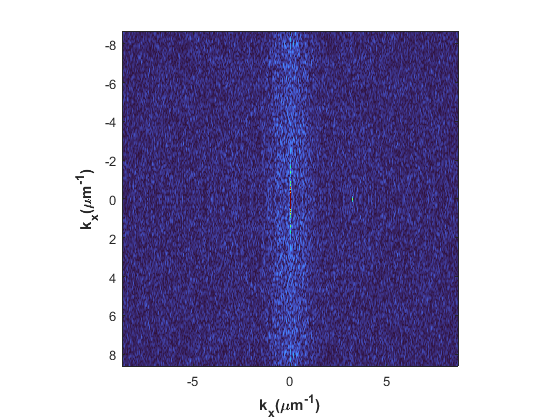

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3new1(:,:,6))))))
xlabel('k_x(\mum^{-1})','FontWeight','Bold')
ylabel('k_x(\mum^{-1})','FontWeight','Bold')
caxis([0 .05])
axis square
colormap Turbo